[MATLAB | 如何绘制二维散点主方向直方图 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247490069&idx=1&sn=cece37270b71d08cb4e68384ca562611&chksm=cf6080bef81709a8bdfa52bc0f21044f590dc6da47b3eac9557cfdfa5241598445695efbc60d&scene=178&cur_album_id=2560715562641768449#rd)

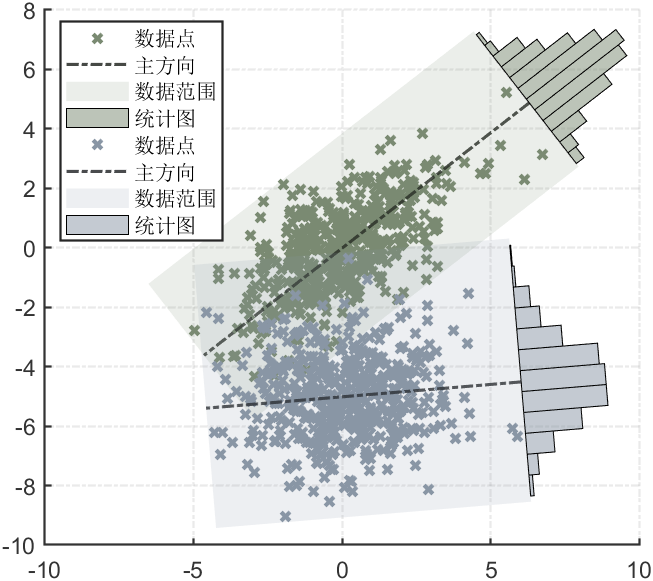

## 基本使用

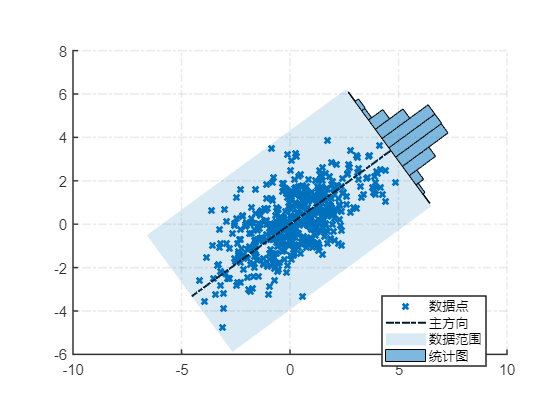

% 随机生成数据
X=mvnrnd([0,0],[3,1.5;1.5,2],500);

% 绘图
[H1,H2,H3,H4]=PCA2Hist(X);

% 创建图例
lgd=legend([H1,H2,H3,H4(1)],'数据点','主方向','数据范围','统计图');
lgd.Location='best';

% 坐标区域修饰
ax=gca;hold on;
ax.DataAspectRatio=[1,1,1];
ax.XGrid='on';
ax.YGrid='on';
ax.XColor=[.2,.2,.2];
ax.YColor=[.2,.2,.2];
ax.GridLineStyle='-.';
ax.GridAlpha=.1;
ax.LineWidth=1.1;
ax.FontSize=11;

## 多组数据

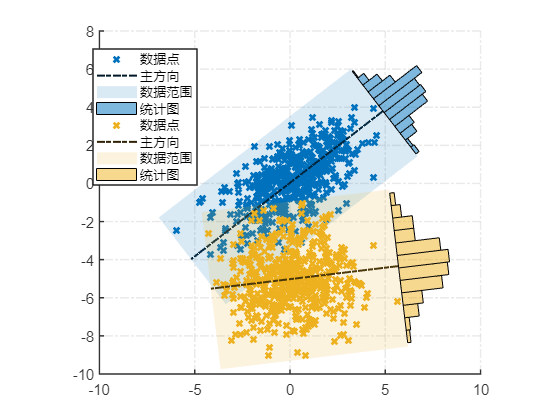

clf;clear
% 随机生成数据
X1=mvnrnd([0,0],[3,1.5;1.5,2],500);
X2=mvnrnd([0,0],[3,.1;.1,2],500)-[0,5];

% 绘图
[H1_1,H1_2,H1_3,H1_4]=PCA2Hist(X1);
[H2_1,H2_2,H2_3,H2_4]=PCA2Hist(X2);

% 创建图例
lgd=legend([H1_1,H1_2,H1_3,H1_4(1),H2_1,H2_2,H2_3,H2_4(1)],...
    '数据点','主方向','数据范围','统计图','数据点','主方向','数据范围','统计图');
lgd.Location='best';

% 坐标区域修饰
ax=gca;hold on;
ax.DataAspectRatio=[1,1,1];
ax.XGrid='on';
ax.YGrid='on';
ax.XColor=[.2,.2,.2];
ax.YColor=[.2,.2,.2];
ax.GridLineStyle='-.';
ax.GridAlpha=.1;
ax.LineWidth=1.1;
ax.FontSize=11;

## 修改配色

设置CData属性即可：

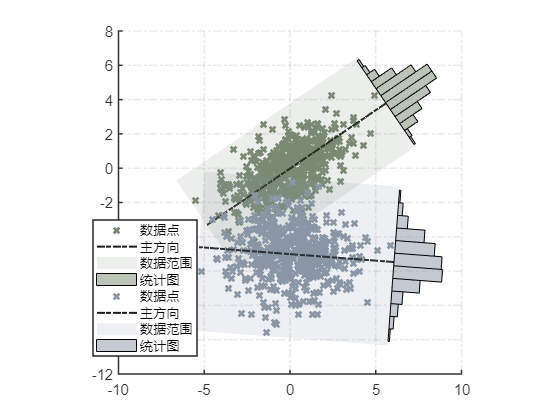

clf;clear
% 随机生成数据
X1=mvnrnd([0,0],[3,1.5;1.5,2],500);
X2=mvnrnd([0,0],[3,.1;.1,2],500)-[0,5];

% 绘图
[H1_1,H1_2,H1_3,H1_4]=PCA2Hist(X1,'CData',[122,138,114]./255);
[H2_1,H2_2,H2_3,H2_4]=PCA2Hist(X2,'CData',[137,150,165]./255);

% 创建图例
lgd=legend([H1_1,H1_2,H1_3,H1_4(1),H2_1,H2_2,H2_3,H2_4(1)],...
    '数据点','主方向','数据范围','统计图','数据点','主方向','数据范围','统计图');
lgd.Location='best';

% 坐标区域修饰 
ax=gca;hold on;
ax.DataAspectRatio=[1,1,1];
ax.XGrid='on';
ax.YGrid='on';
ax.XColor=[.2,.2,.2];
ax.YColor=[.2,.2,.2];
ax.GridLineStyle='-.';
ax.GridAlpha=.1;
ax.LineWidth=1.1;
ax.FontSize=11;

## 精细修饰

对返回的四个对象进行属性设置即可，比如把方向线改为红色，将散点改为圆点：

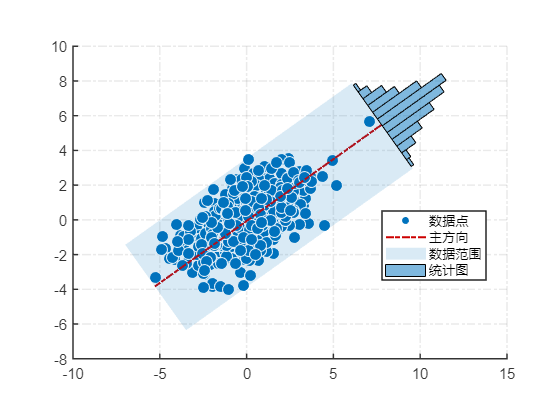

clf;clear
% 随机生成数据
X=mvnrnd([0,0],[3,1.5;1.5,2],500);

% 绘图
[H1,H2,H3,H4]=PCA2Hist(X);

% 图形对象修饰
H1.Marker='o';
H1.MarkerFaceColor=H1.CData;
H1.MarkerEdgeColor=[1,1,1];
H1.SizeData=80;
H1.LineWidth=.8;

H2.Color=[.8,0,0];

% 创建图例
lgd=legend([H1,H2,H3,H4(1)],'数据点','主方向','数据范围','统计图');
lgd.Location='best';

% 坐标区域修饰
ax=gca;hold on;
ax.DataAspectRatio=[1,1,1];
ax.XGrid='on';
ax.YGrid='on';
ax.XColor=[.2,.2,.2];
ax.YColor=[.2,.2,.2];
ax.GridLineStyle='-.';
ax.GridAlpha=.1;
ax.LineWidth=1.1;
ax.FontSize=11;

输入nx2大小的数组，返回以下四个图形对象:

H1: '数据点'

H2: '主方向'

H3: '数据范围'

H4: '统计图'

function [H1,H2,H3,H4]=PCA2Hist(X,varargin)
% H1: '数据点'
% H2: '主方向'
% H3: '数据范围'
% H4: '统计图'

% PCA-Hist
% rng(12)
hold on
H1=scatter(X(:,1),X(:,2),'x','LineWidth',2,varargin{:});


% 求主方向
Xmean=mean(X);
X0=X-Xmean;
covMat=cov(X0);;
[V,~]=eigs(covMat,1);
V=V.*sign(V(1));
Vc=[V(2);-V(1)];
Lp=max(X0*V);
Ln=min(X0*V);
Ll=max(X0*Vc);
Lr=min(X0*Vc);

% 绘制统计图
H2=plot(Xmean(1)+[Lp,Ln].*V(1).*1.05,Xmean(2)+[Lp,Ln].*V(2).*1.05,'Color',[H1.CData./5,.8],'LineStyle','-.','LineWidth',1.5);
H3=fill(Xmean(1)+[Lp,Lp,Ln,Ln].*V(1).*1.05+[Ll,Lr,Lr,Ll].*Vc(1).*1.05,...
     Xmean(2)+[Lp,Lp,Ln,Ln].*V(2).*1.05+[Ll,Lr,Lr,Ll].*Vc(2).*1.05,... 
    H1.CData,'FaceAlpha',.15,'EdgeColor','none');

histHdl=histogram(X0*Vc,'BinEdges',linspace(Lr,Ll,13),'Visible','off');
maxValue=max(histHdl.Values);
for i=1:histHdl.NumBins
    H4(i)=fill(Xmean(1)+[histHdl.BinEdges(i).*Vc(1)+Lp.*V(1).*1.05,...
        histHdl.BinEdges(i).*Vc(1)+Lp.*V(1).*1.05+histHdl.Values(i).*Lp.*V(1).*0.5./maxValue,...
        histHdl.BinEdges(i+1).*Vc(1)+Lp.*V(1).*1.05+histHdl.Values(i).*Lp.*V(1).*0.5./maxValue,...
        histHdl.BinEdges(i+1).*Vc(1)+Lp.*V(1).*1.05],...
        Xmean(2)+[histHdl.BinEdges(i).*Vc(2)+Lp.*V(2).*1.05,...
        histHdl.BinEdges(i).*Vc(2)+Lp.*V(2).*1.05+histHdl.Values(i).*Lp.*V(2).*0.5./maxValue,...
        histHdl.BinEdges(i+1).*Vc(2)+Lp.*V(2).*1.05+histHdl.Values(i).*Lp.*V(2).*0.5./maxValue,...
        histHdl.BinEdges(i+1).*Vc(2)+Lp.*V(2).*1.05],...
        H1.CData,'FaceAlpha',.5);

end
end